clear; close all; clc;

**Question 1: Calculate the Radon transform of an image and test the back-projection method.**

Load an image of the Shepp-Logan phantom of size 128x128. We will refer to this as ftrue. Show a picture of f.

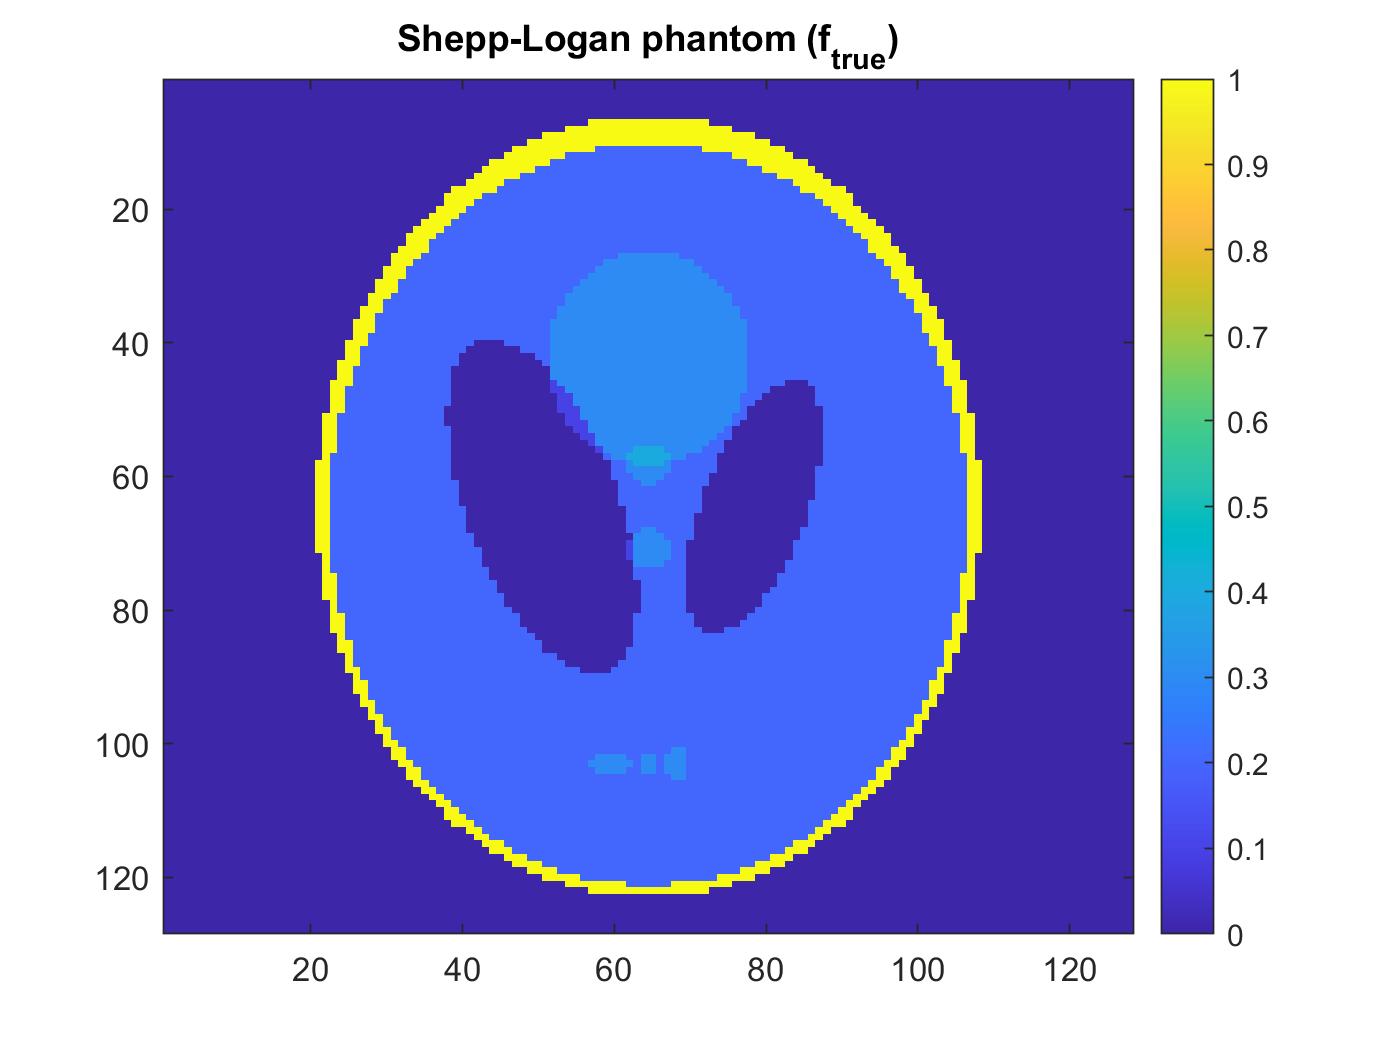

n = 128;
f = phantom('Modified Shepp-Logan', n);

figure; imagesc(f); colorbar; title('Shepp-Logan phantom (f_{true})')

Generate the Radon transform g = Rf of this phantom in 1-degree intervals from 0-179. Display g as a 2D-image; this is referred to as the sinogram of ftrue. What is the size of this sinogram and how is this determined?

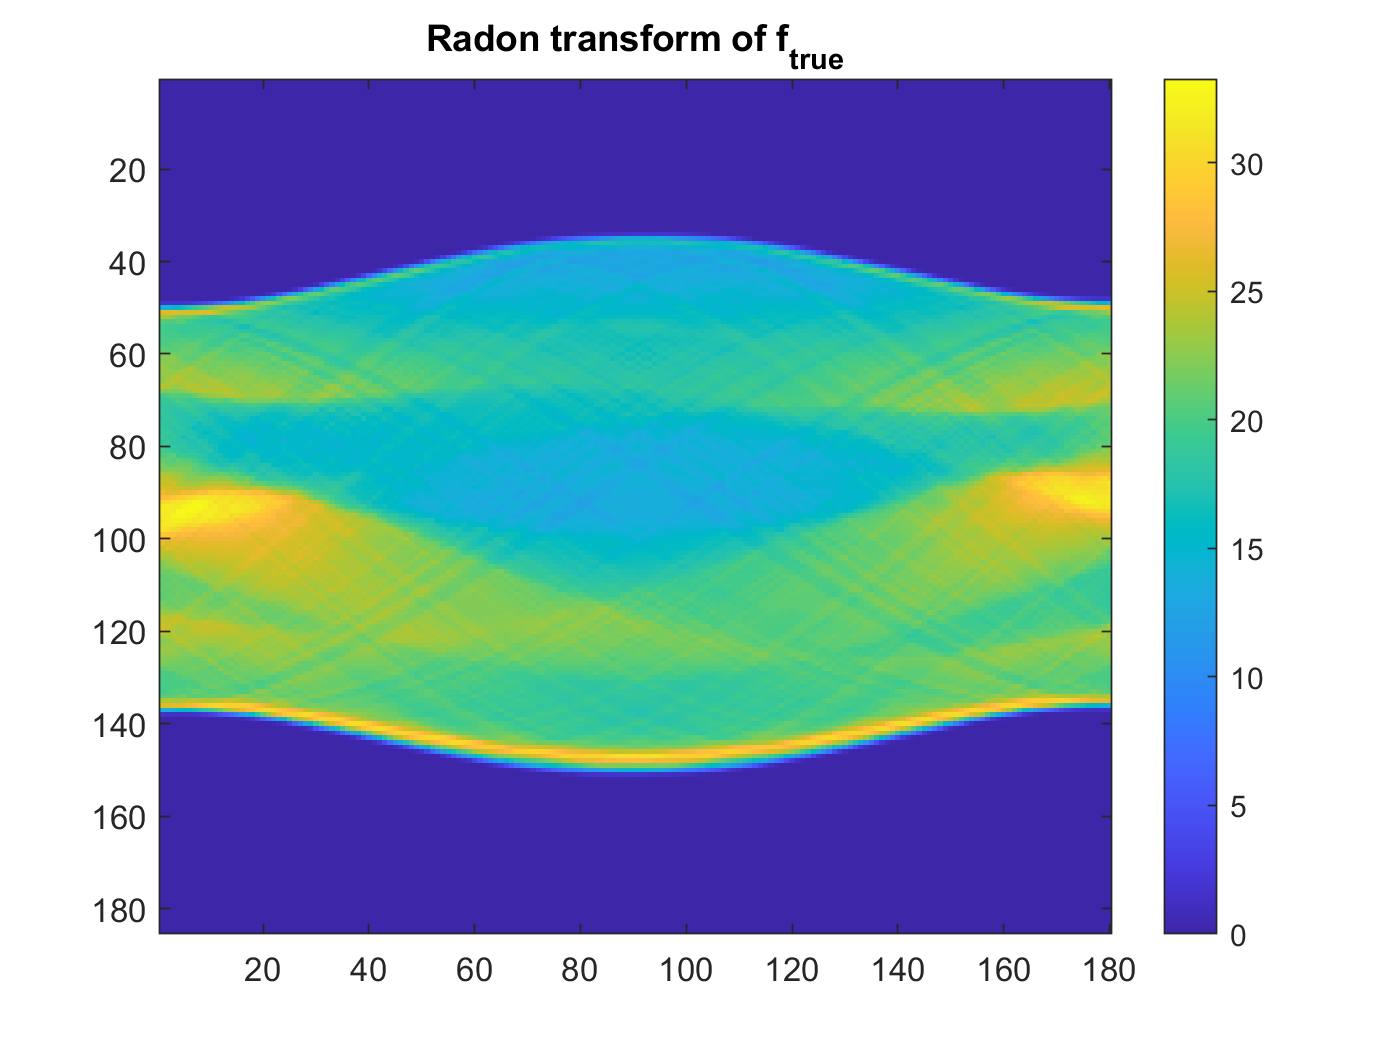

angles = 0 : 1 : 179;

g = radon(f, angles);

figure; imagesc(g); colorbar; title('Radon transform of f_{true}');

size(g)

ans =    185   180


Compute the unfiltered back-projection and apply it to the sinogram data you generated. What is the size of the back-projected image?

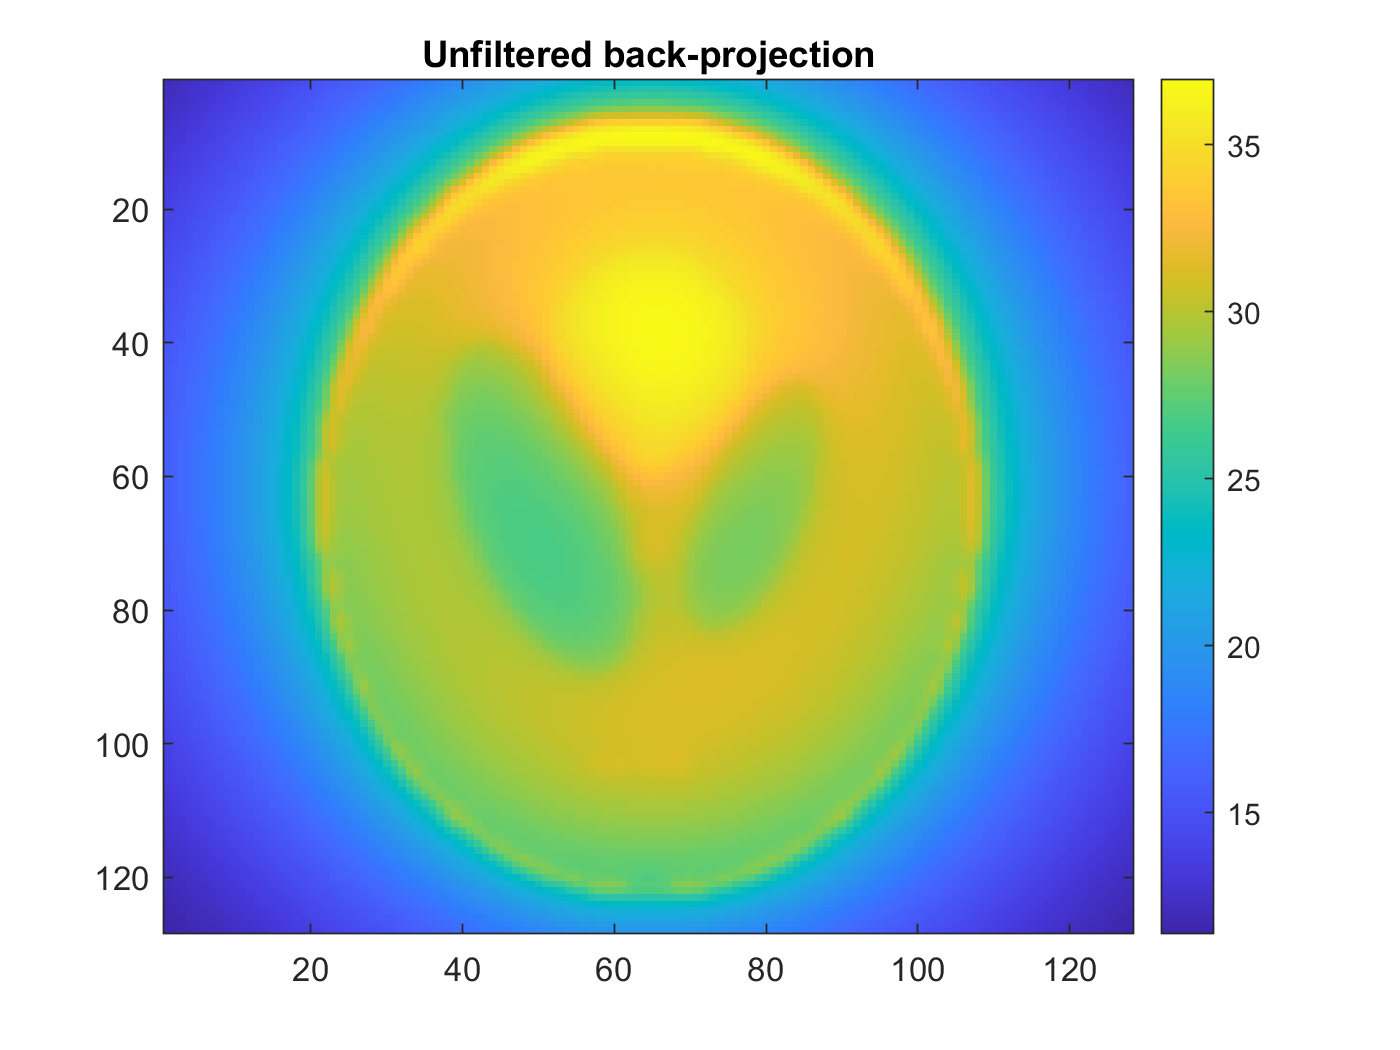

back_projection_unfiltered = iradon(g, angles, 'linear', 'none', 1, n);

figure;
imagesc(back_projection_unfiltered);
colorbar;
title('Unfiltered back-projection')

Compute the �ltered back-projection and apply it to the sinogram data g that you generated. Verify that this gives a good estimate of the inverse of the Radon transform.

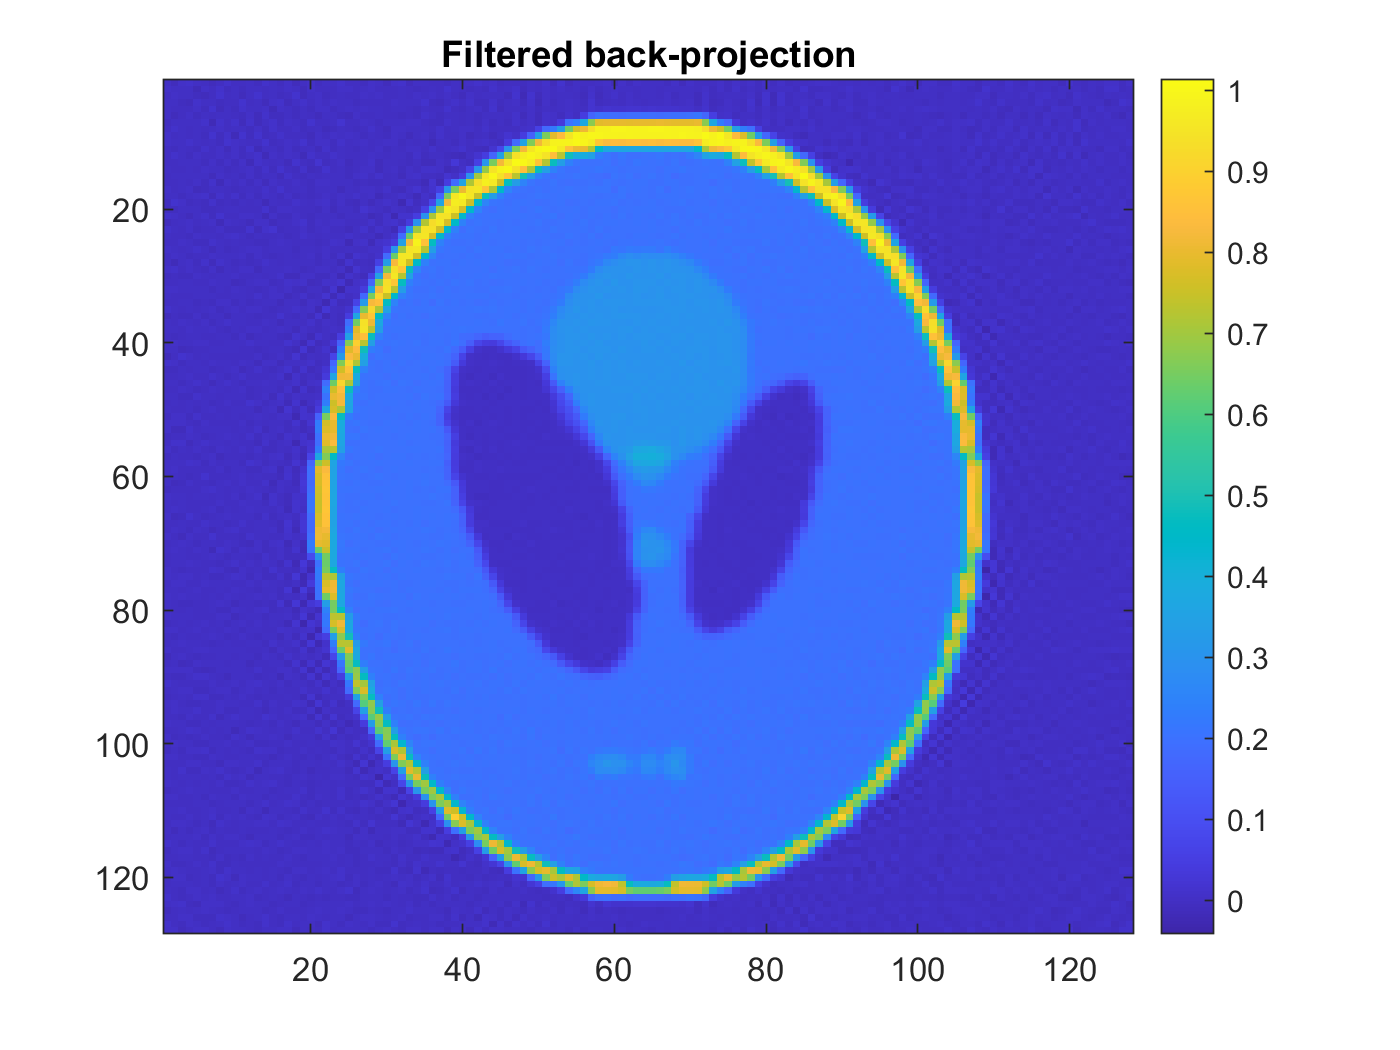

back_projection = iradon(g, angles, 'linear', 'Shepp-Logan', 1, n);

figure;
imagesc(back_projection);
colorbar;
title('Filtered back-projection')

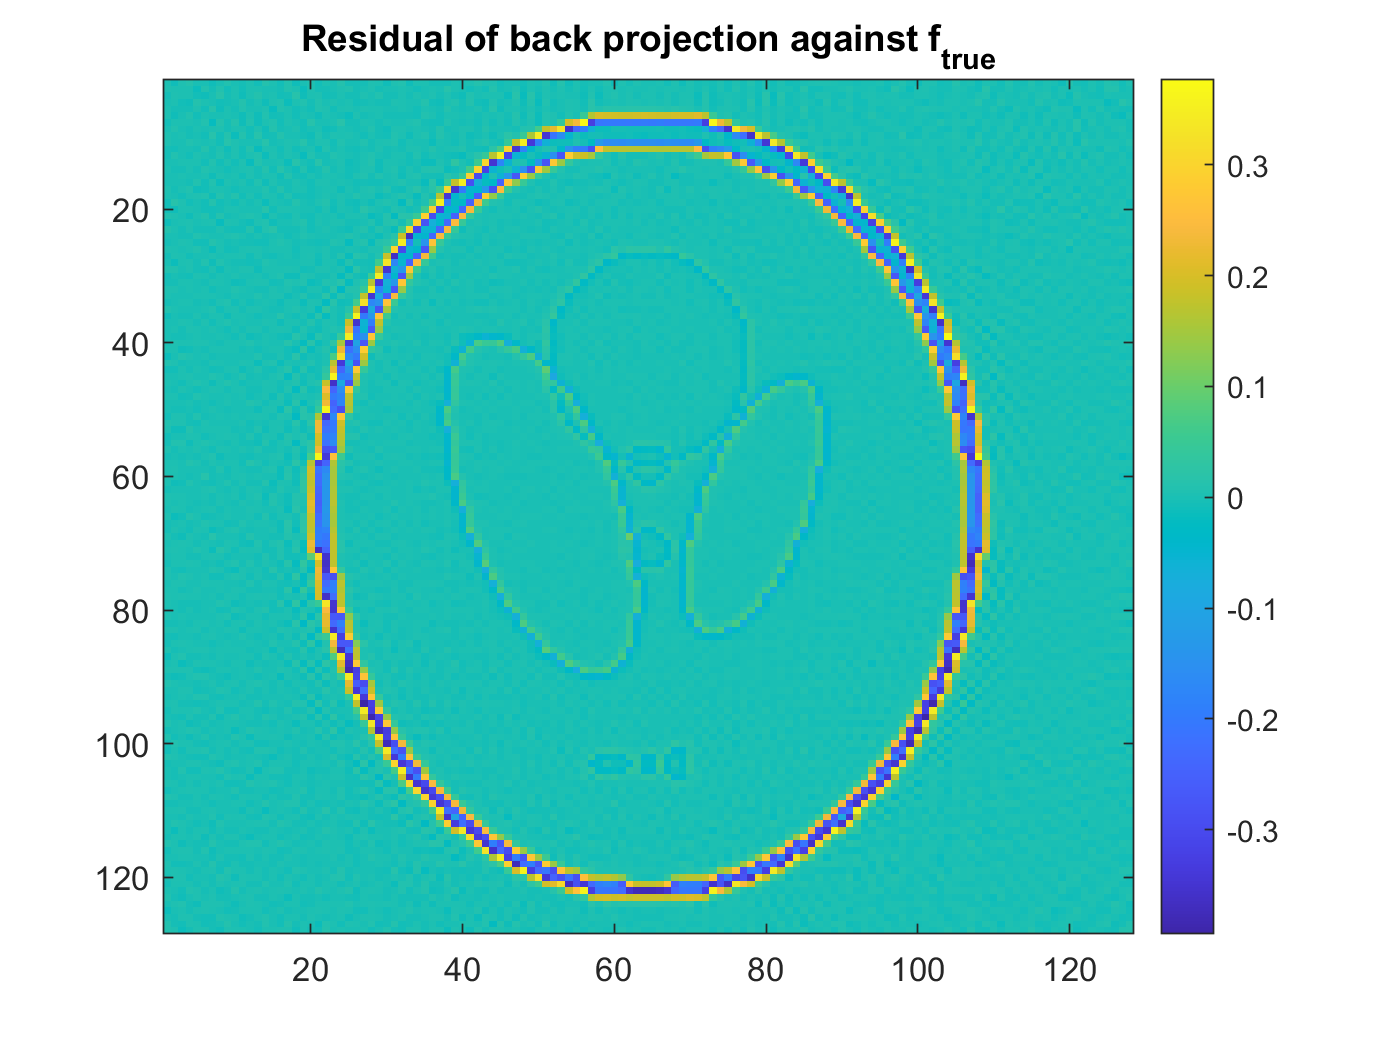

diff = back_projection - f;

figure;
imagesc(diff);
colorbar;
title('Residual of back projection against f_{true}');

residual = sum(sum(diff.^2)) / (n * n)

residual = 0.0043

Add noise to the data g and test how the error in your reconstruction grows with the scale of the measurement noise.

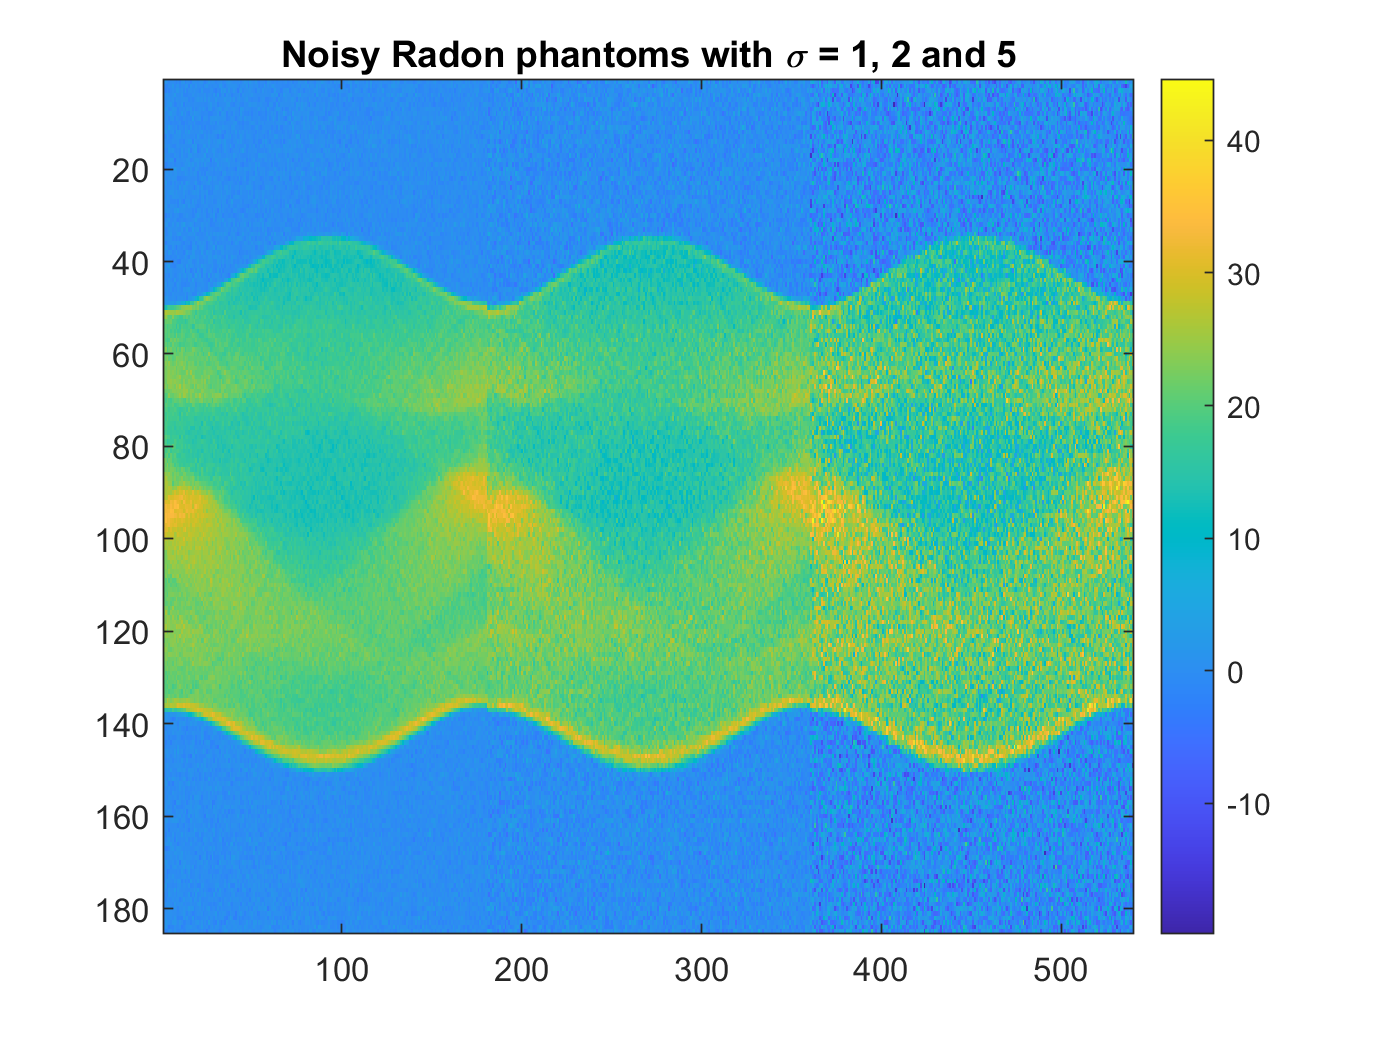

g_noisy1 = noisy_phantom(angles, 1, n);
g_noisy2 = noisy_phantom(angles, 2, n);
g_noisy3 = noisy_phantom(angles, 5, n);

figure;
imagesc([g_noisy1, g_noisy2, g_noisy3]);
colorbar;
title('Noisy Radon phantoms with \sigma = 1, 2 and 5')

bp_g_noisy1 = iradon(g_noisy1, angles, 'linear', 'Shepp-Logan', 1, n);
bp_g_noisy2 = iradon(g_noisy2, angles, 'linear', 'Shepp-Logan', 1, n);
bp_g_noisy3 = iradon(g_noisy3, angles, 'linear', 'Shepp-Logan', 1, n);

residual_gn1 = sum(sum((bp_g_noisy1 - f).^2)) / (n * n)

residual_gn1 = 0.0058

residual_gn2 = sum(sum((bp_g_noisy2 - f).^2)) / (n * n)

residual_gn2 = 0.0100

residual_gn3 = sum(sum((bp_g_noisy3 - f).^2)) / (n * n)

residual_gn3 = 0.0400